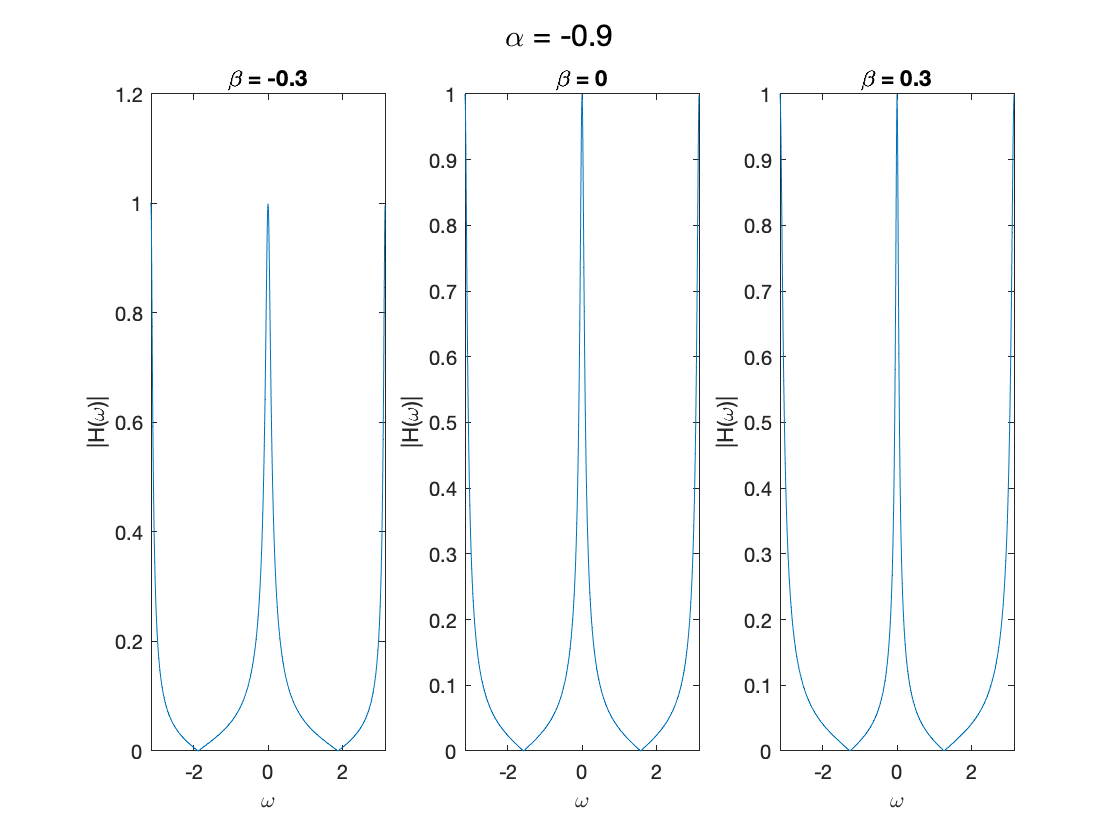

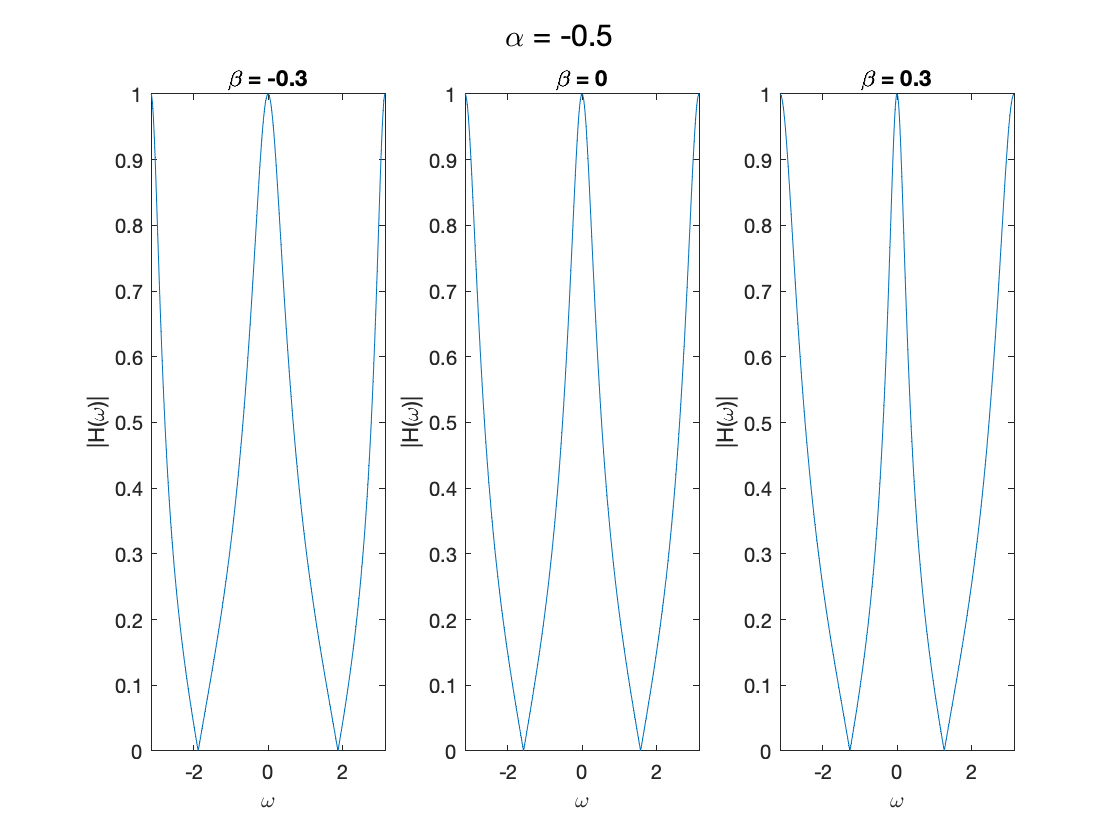

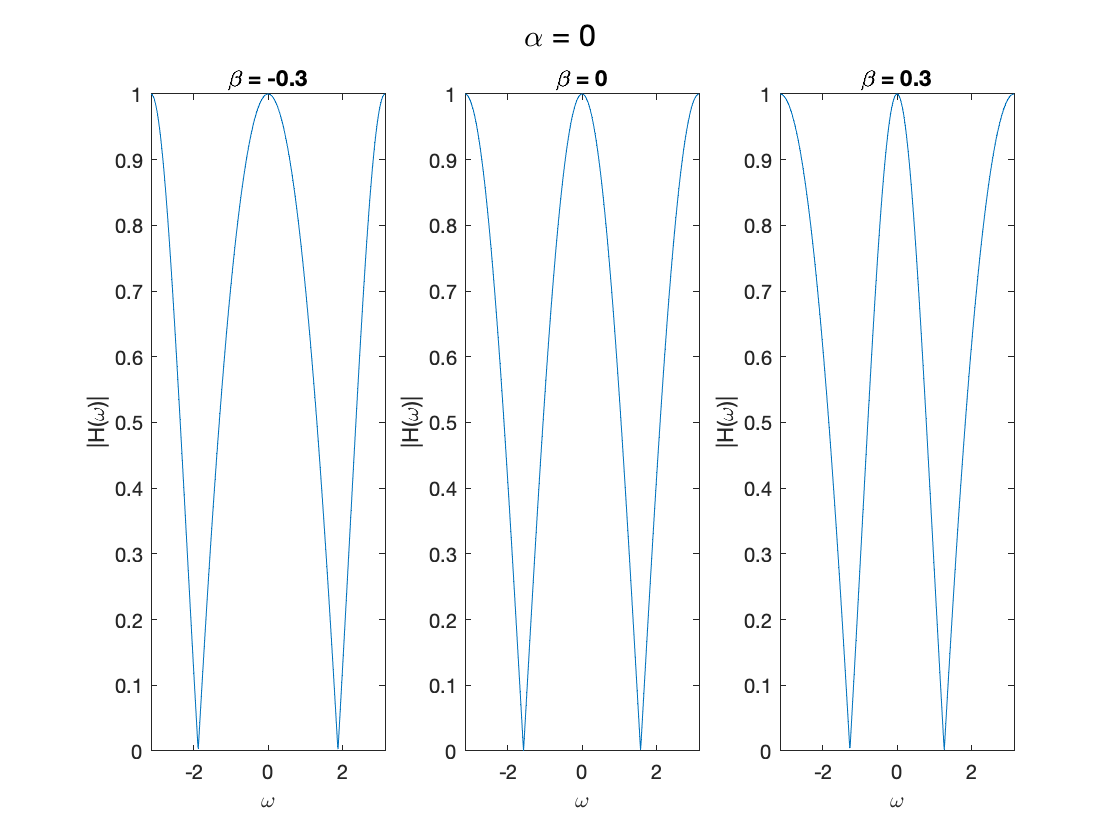

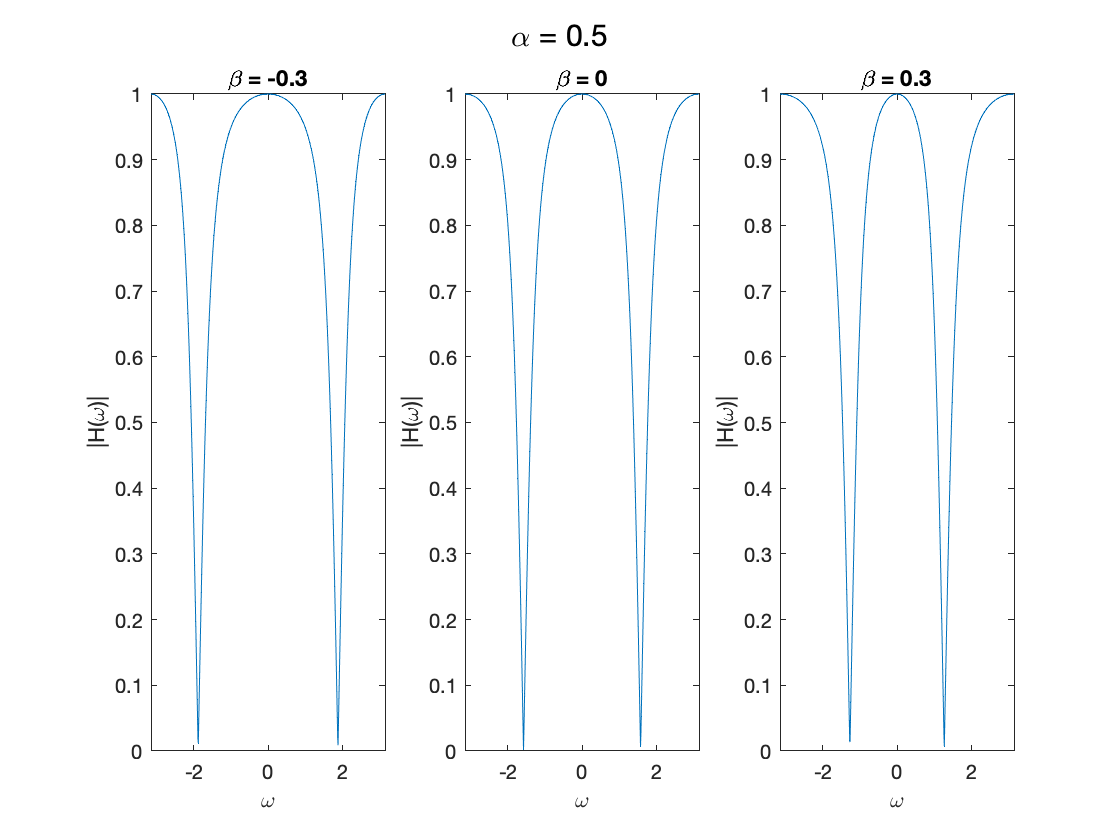

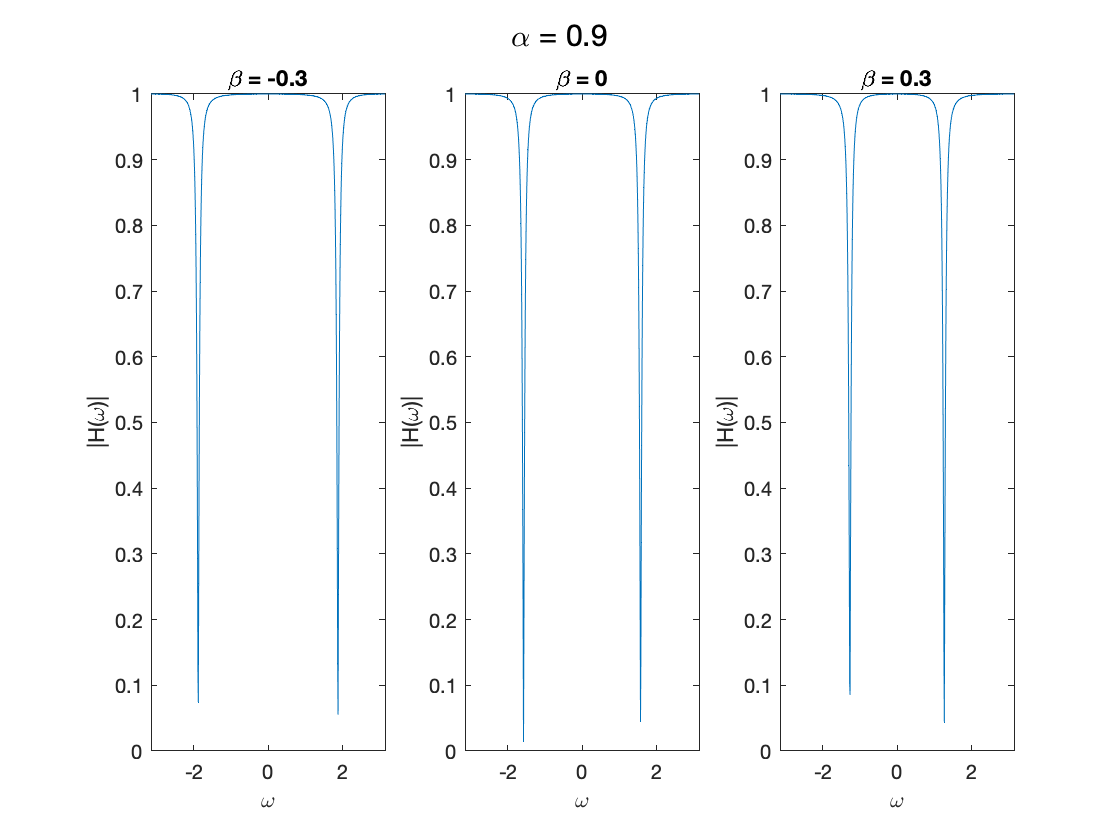

% Q1
w = -pi:0.01:pi;

Hw_ab = @(a, b, w) ((1+a)/2) .* (1-2.*b.*exp(-1j.*w)+exp(-2j.*w)) ./ ...
    (1-b.*(1+a).*exp(-1j.*w)+a.*exp(-2j.*w));

a_values = [-0.9, -0.5, 0, 0.5, 0.9];
b_values = [-0.3, 0, 0.3];

for i=1:length(a_values)
    figure;
    for j=1:length(b_values)
        a = a_values(i);
        b = b_values(j);
        
        Hw = Hw_ab(a, b, w);
        
        subplot(1, length(b_values), j);
        plot(w, abs(Hw));
        xlabel("\omega"); ylabel("|H(\omega)|");
        title("\beta = "+b);
    end
    sgtitle("\alpha = "+a);
end

i) From the above plots, it is clear that the filter is a **Band Stop Filter (BSF)**.

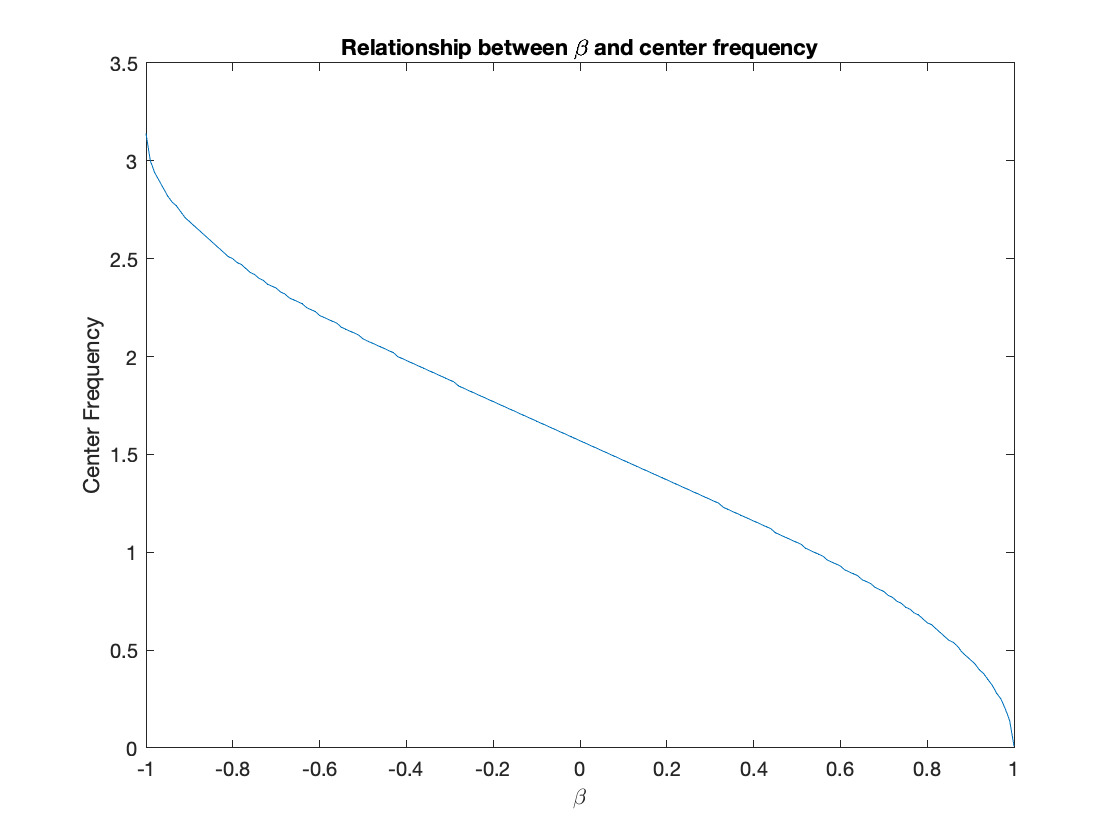

pos_w = 0:0.01:pi;
b_range = -1:0.01:1;
cen_freq = zeros(1, length(b_range));
for i=1:length(b_range)
    b = b_range(i);
    Hw = Hw_ab(0, b, pos_w);
    [minVal, minIndex] = min(Hw);
    current_cen_freq = pos_w(minIndex);
    cen_freq(i) = current_cen_freq;
end
figure;
plot(b_range, cen_freq);
xlabel("\beta"); ylabel("Center Frequency");
title("Relationship between \beta and center frequency");

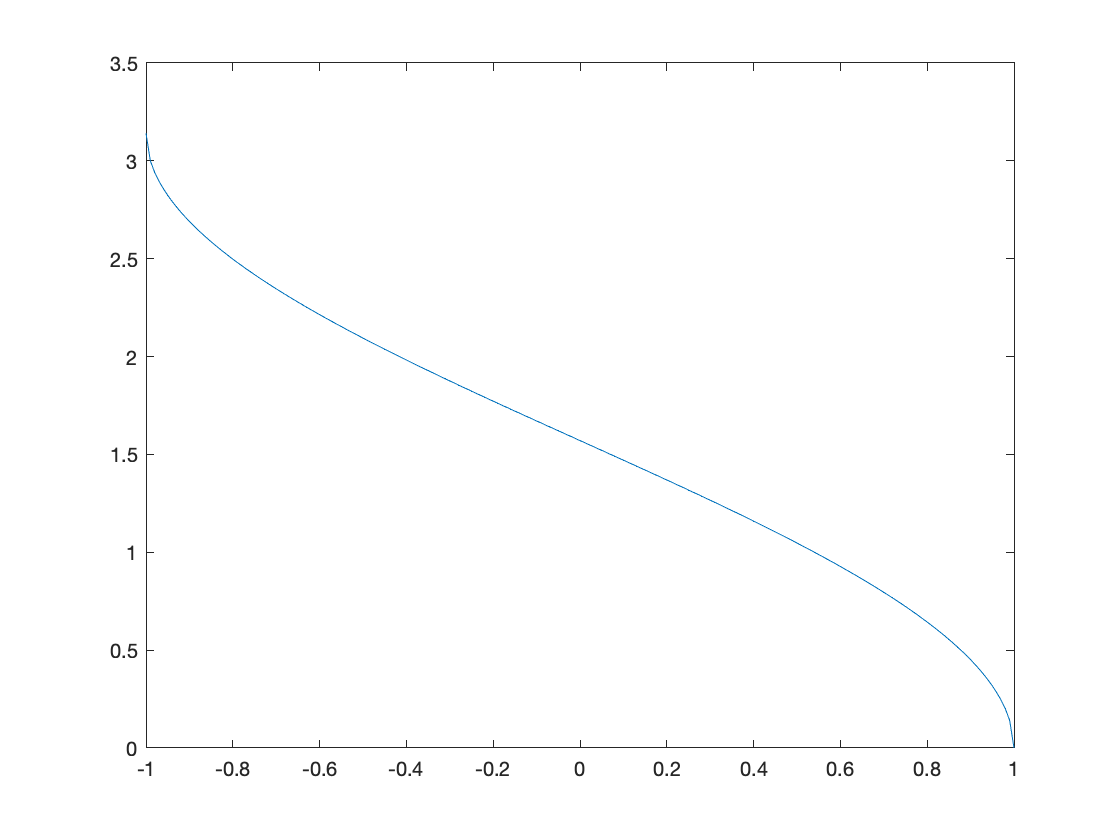

figure;
plot(b_range, pi/2 - asin(b_range));

ii, a) Since the above two plots are almost identical, we can say that the relationship between $\beta$ and center frequecy is given by:


$$f_c = \frac{\pi}{2} - sin^{-1}(\beta)$$


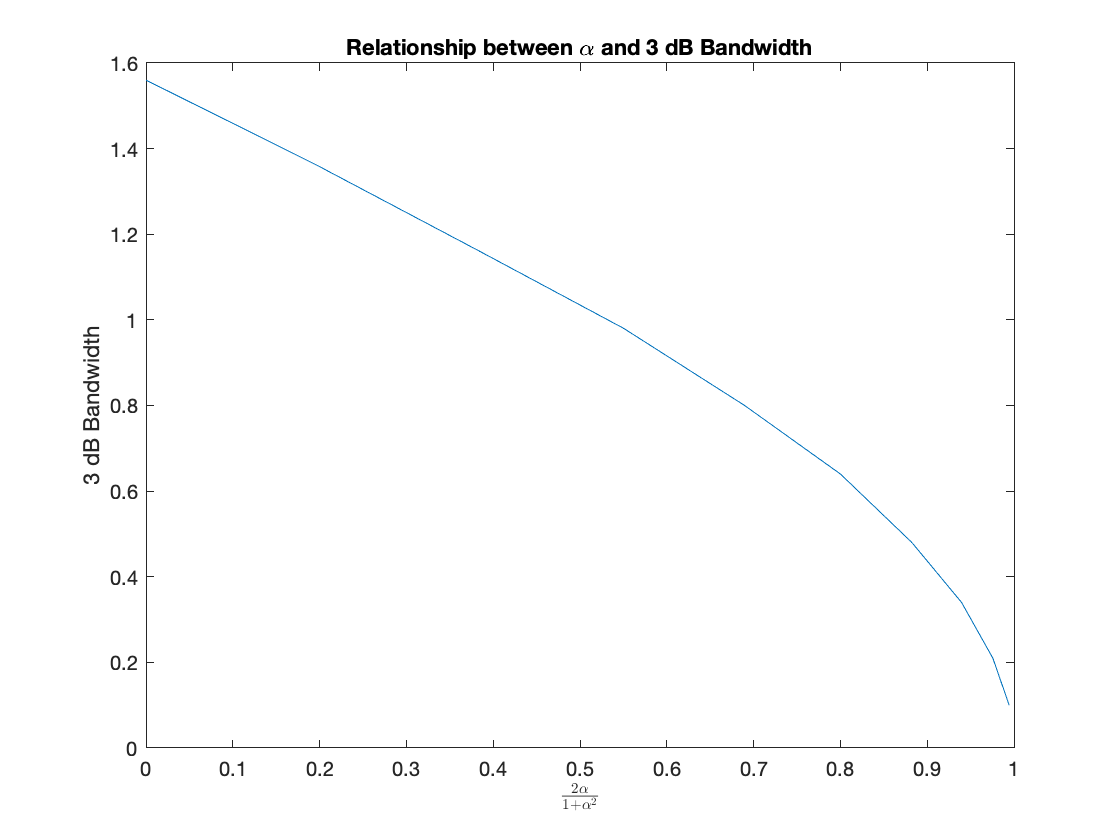

a_range = 0:0.1:0.9;
% a_range = [0, 0.2, 0.5];
a_expression = 2 .* a_range ./ (1 + a_range.^2);
bandwidth = zeros(1, length(a_range));
for i = 1:length(a_range)
    a = a_range(i);
    Hw = abs(Hw_ab(a, 0, pos_w));
%     figure;
%     plot(pos_w, Hw);
    i1 = find(Hw <= (1/sqrt(2)), 1);
    i2 = length(Hw) - find(flip(Hw) <= (1/sqrt(2)), 1) + 1;
    wp1 = pos_w(i1);
    wp2 = pos_w(i2);
    bandwidth(i) = wp2 - wp1;
end
figure;
plot(a_expression, bandwidth);
xlabel("$\frac{2\alpha}{1+\alpha^2}$", "Interpreter","latex");
ylabel("3 dB Bandwidth");
title("Relationship between \alpha and 3 dB Bandwidth");

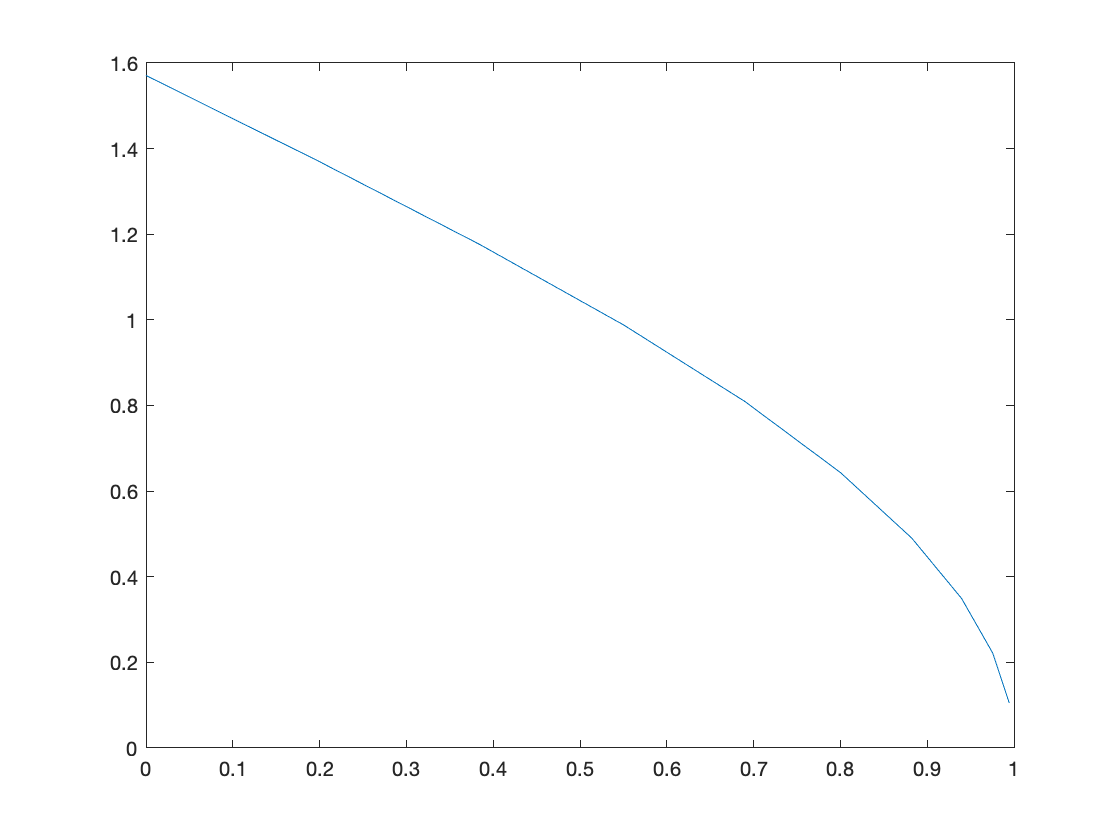

plot(a_expression, acos(a_expression));

ii, b) Since the above two plots are almost identical, we can say that the relationship between $\left|\frac{2\alpha}{1+\alpha^2}\right|$ and 3 dB Bandwidth is given by:

3 dB Bandwidth = $cos^{-1}\left(\left|\frac{2\alpha}{1+\alpha^2}\right|\right)$

Hence, we can say that increase in the value of $\alpha$ allows more frequencies to pass through the filter (3 dB bandwidth decreases), and increase in the value of $\beta$ reduces the amount of low frequencies that can pass through the filter (center frequency decreases).

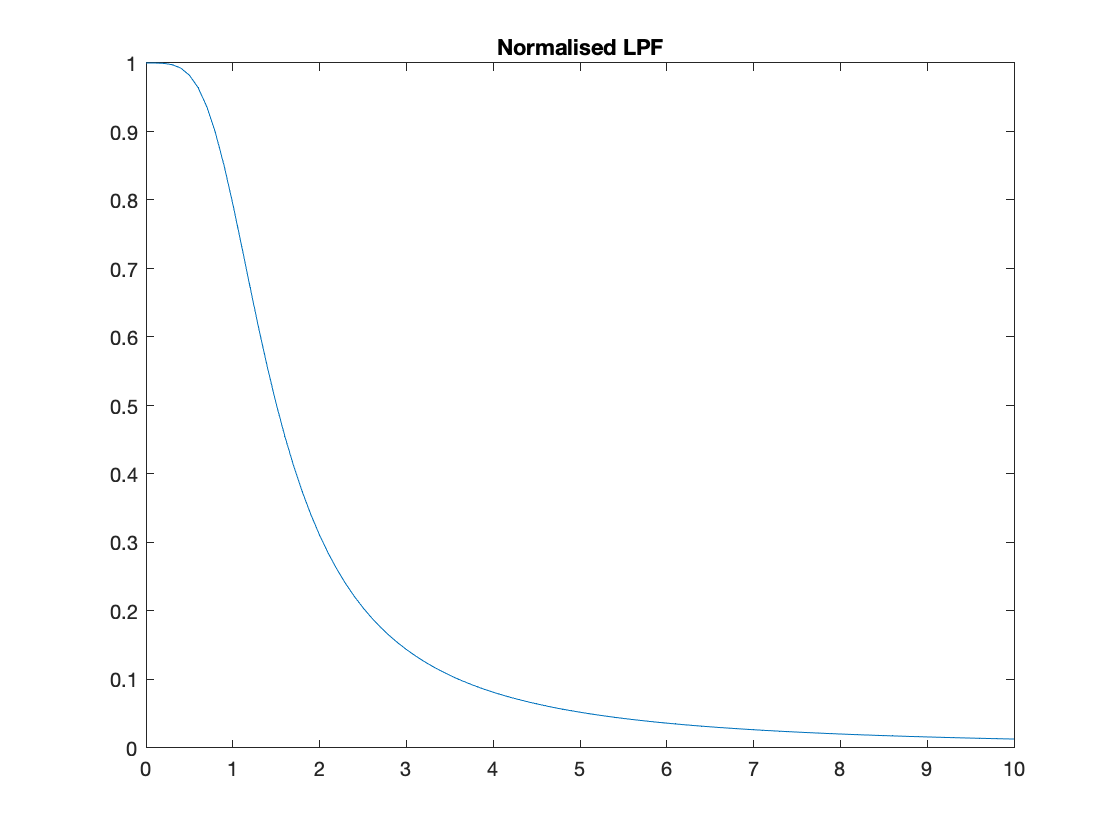

% Q2 (a)
% Given filter specifications
Ap = -2; %dB
As = -20; %dB
fp1 = 800;
fp2 = 1000;
fs1 = 400;
fs2 = 2000;
f_sampling = 8000;

% Converting tolerance values from dB to magnitude
dp = 10^(Ap/20);
ds = 10^(As/20);

% Normalised frequencies
wp1 = 2*pi * fp1/f_sampling;
wp2 = 2*pi * fp2/f_sampling;
ws1 = 2*pi * fs1/f_sampling;
ws2 = 2*pi * fs2/f_sampling;

% Analog equivalent of frequencies
Wp1 = tan(wp1/2);
Wp2 = tan(wp2/2);
Ws1 = tan(ws1/2);
Ws2 = tan(ws2/2);
% Center frequency and bandwidth
W0 = sqrt(Wp1*Wp2);
B = Wp2 - Wp1;

% Modifyying specs if required
if (Ws1*Ws2 < Wp1*Wp2)
    Ws1 = Wp1*Wp2 / Ws2;
elseif (Ws1*Ws2 > Wp1*Wp2)
    Ws2 = Wp1*Wp2 / Ws1;
end

% Finding Normalised stopband frequency
Wsn = (Ws2 - Ws1)/(Wp2 -  Wp1);

% Designing Normalised Butterworth LPF
Nb = ceil(log10(sqrt((ds^(-2) - 1)/(dp^(-2) - 1)))/log10(Wsn));
Wcn = (dp^(-2) - 1)^(-0.5/Nb);

% Normalised LPF Magnitude response
Ha_nlpf = @(W) 1 ./ sqrt(1 + (W/Wcn).^(2*Nb));
Wn_range = 0:0.1:10;
plot(Wn_range, Ha_nlpf(Wn_range));
title("Normalised LPF");

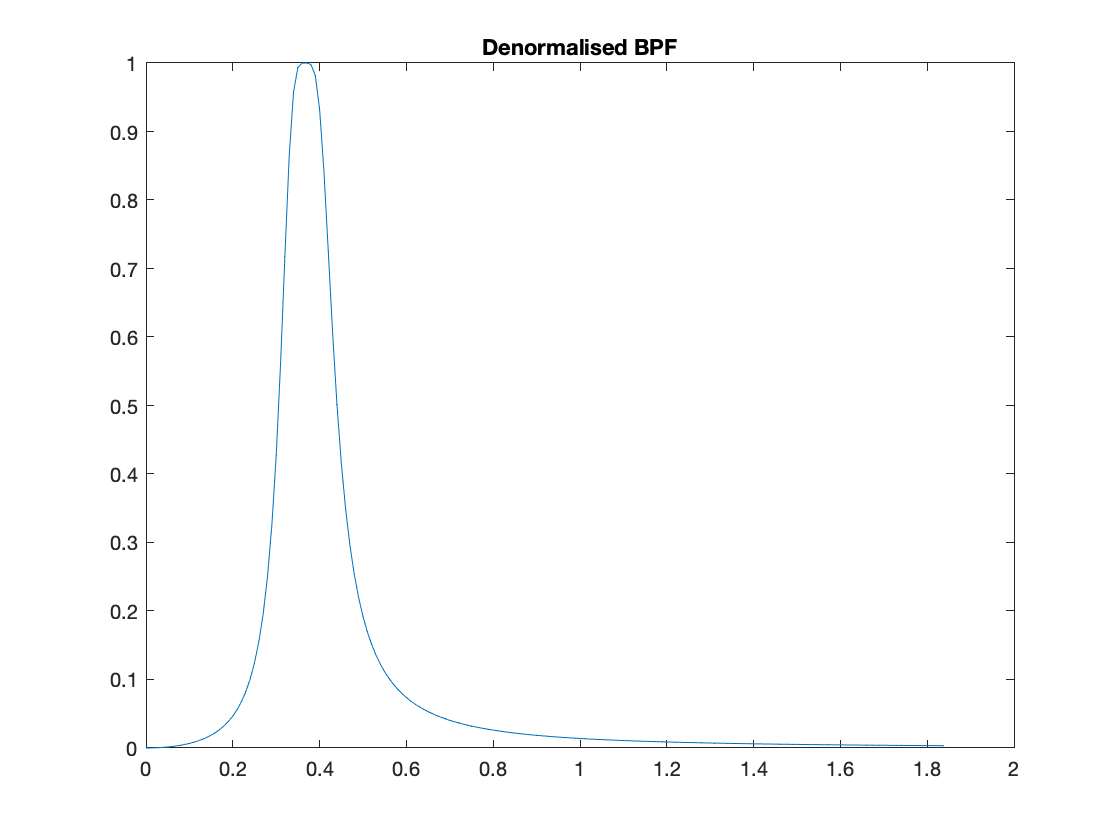

% Frequency transformation to get Denormalised BPF
freq_transformation = @(W) (W.^2 - W0^2)./(W .* B);
Ha_dnbpf = @(W) Ha_nlpf(freq_transformation(W));
% W_range = 0.1:0.1:2;
W_range = 0:0.01:Ws2+1;
plot(W_range, Ha_dnbpf(W_range));
title("Denormalised BPF");

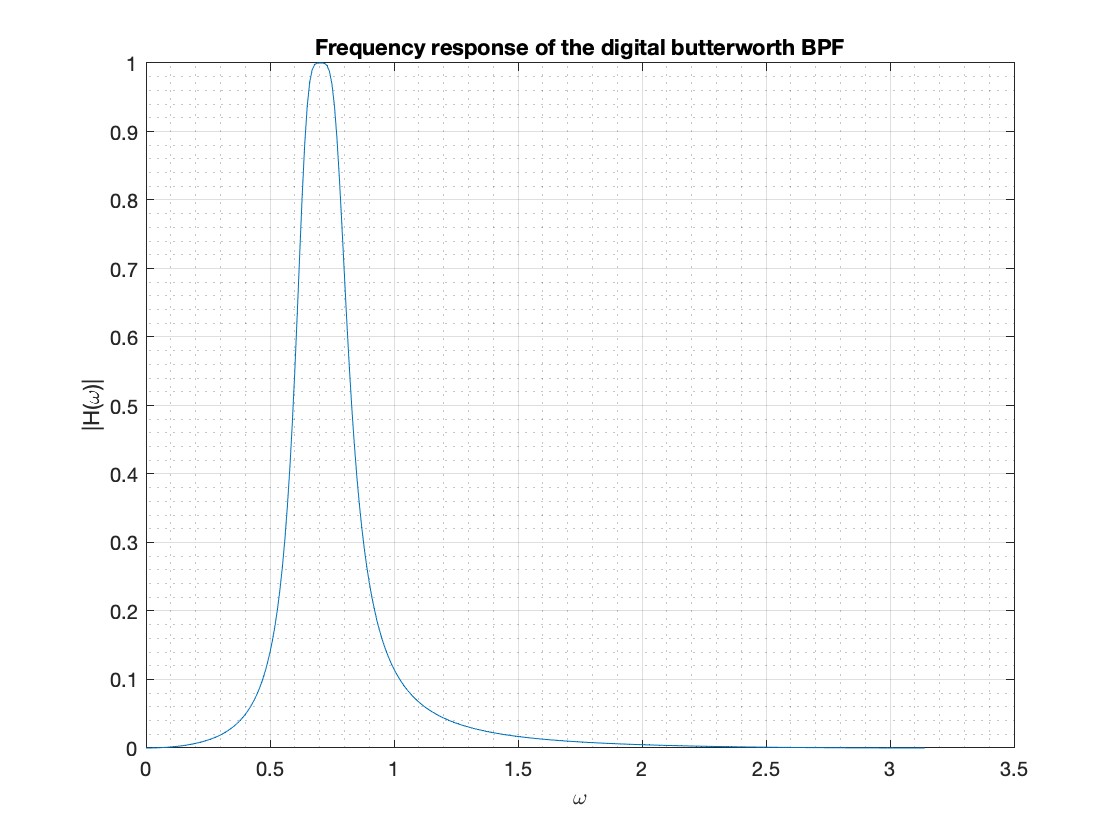

% Bilinear tranformation to get digital filter
w = 0:0.01:pi;
blt = @(w) tan(w/2);
Hw = Ha_dnbpf(blt(w));
plot(w, Hw);
grid on; grid minor; 
xlabel("\omega"); ylabel("|H(\omega)|");
title("Frequency response of the digital butterworth BPF");

fprintf(sprintf("d_p\t d_s\t ws1\t wp1\t wp2\t ws2\t Nb")...
    + "\n" + sprintf("%0.3f\t", [dp, ds, ws1, wp1, wp2, ws2, Nb]));

d_p	 d_s	 ws1	 wp1	 wp2	 ws2	 Nb
0.794	0.100	0.314	0.628	0.785	1.571	2.000	

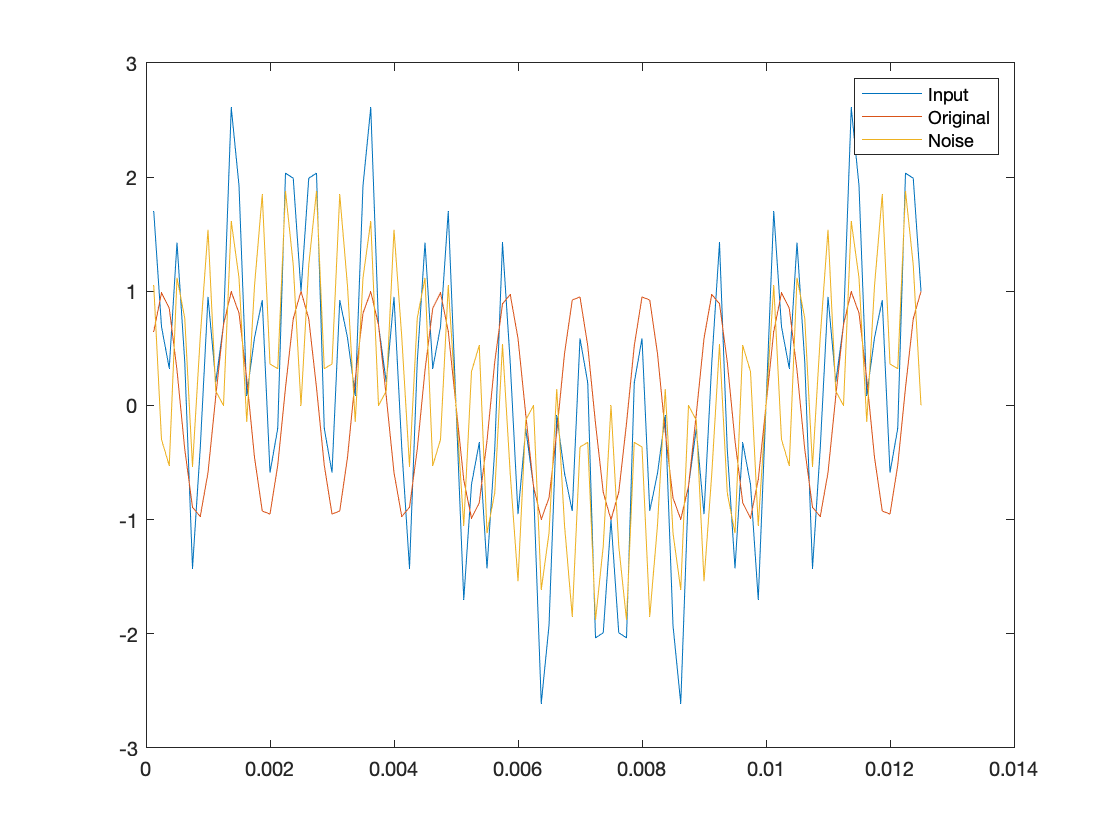

% (b)
f1 = 100;
f2 = 900;
f3 = 2300;

n = 1:100;
T = 1./f_sampling; 

x1 = sin(2*pi * f1 .* n .* T);
x2 = sin(2*pi * f2 .* n .* T);
x3 = sin(2*pi * f3 .* n .* T);
x_in = x1 + x2 + x3;

plot(n*T, x_in, n*T, x2, n*T, x1+x3); 
legend(["Input", "Original", "Noise"]);

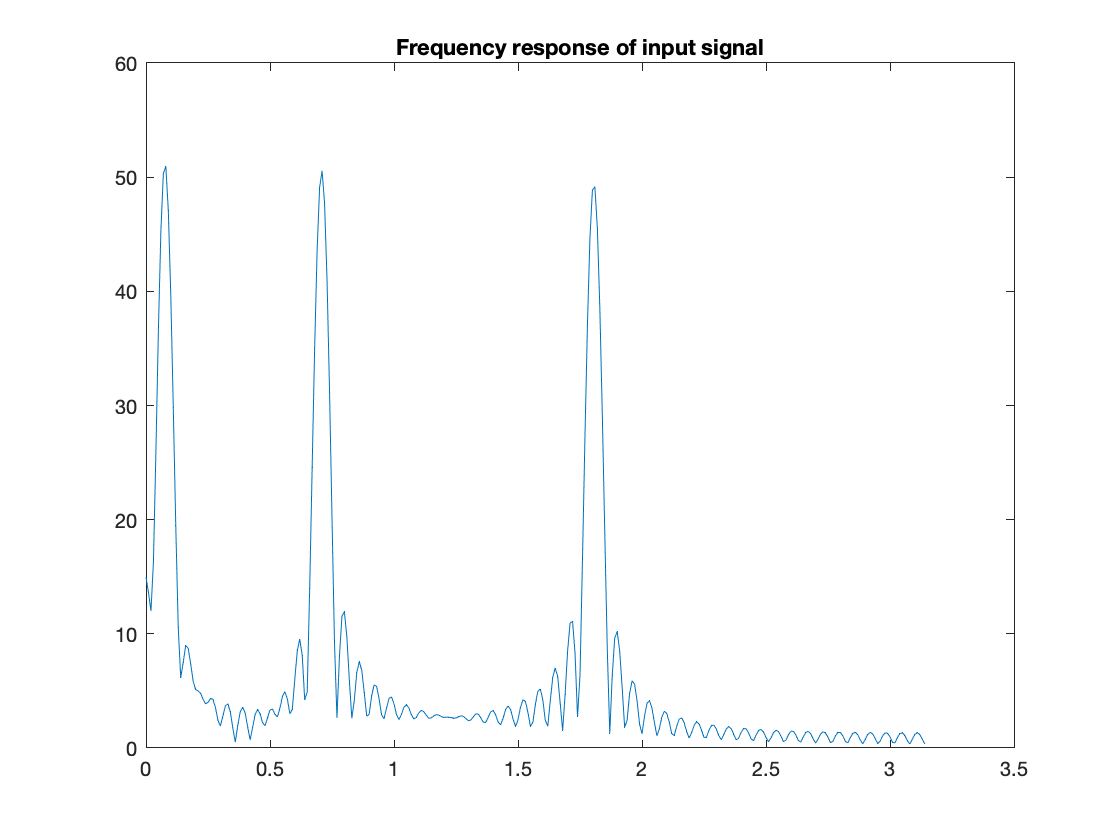

dtft = @(xn, n, w) (exp(-1j .* (w' * n)) * xn')';
idtft = @(Xw, w, n) (exp(1j .* (n' * w)) * Xw')' ./ length(w); 
X_in = dtft(x_in, n, w);
plot(w, abs(X_in)); title("Frequency response of input signal");

fprintf("component frequencies: " + sprintf("%.3f ", [f1 f2  f3] * (2*pi*T)));

component frequencies: 0.079 0.707 1.806 

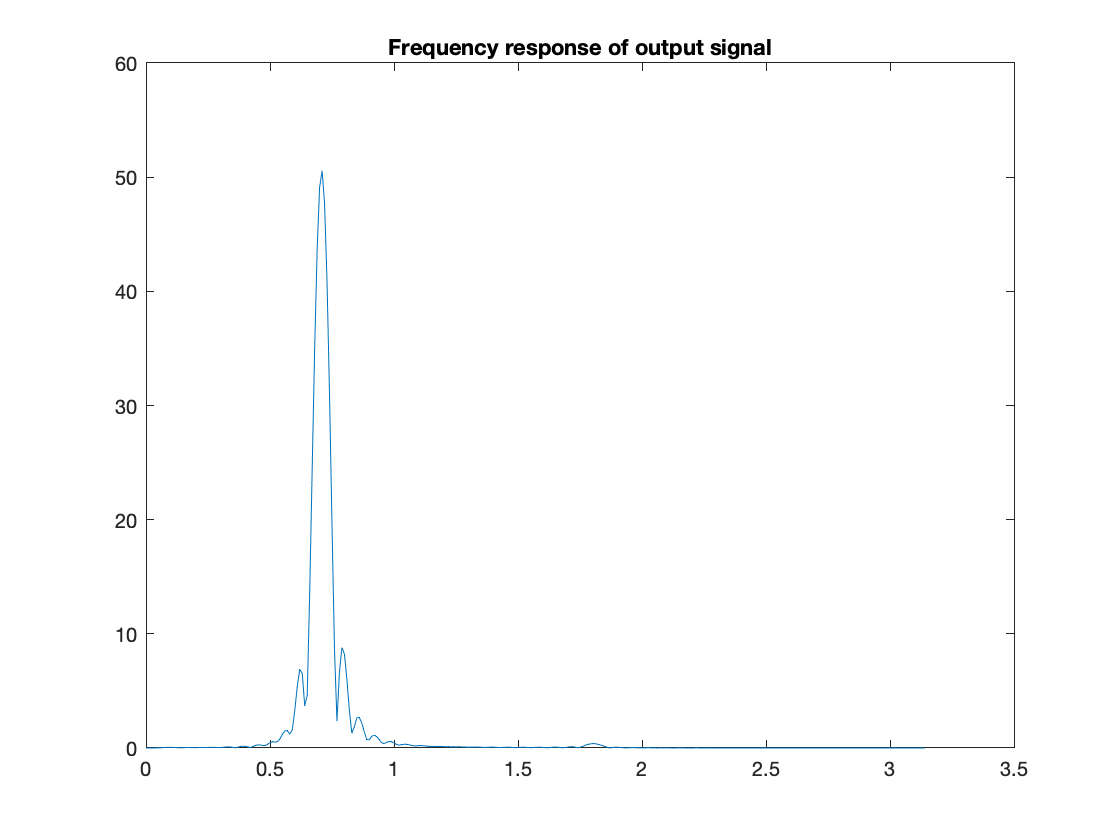

X_out = X_in .* Hw;
% X_out = abs(X_in) .* filter3;
plot(w, abs(X_out)); title("Frequency response of output signal");

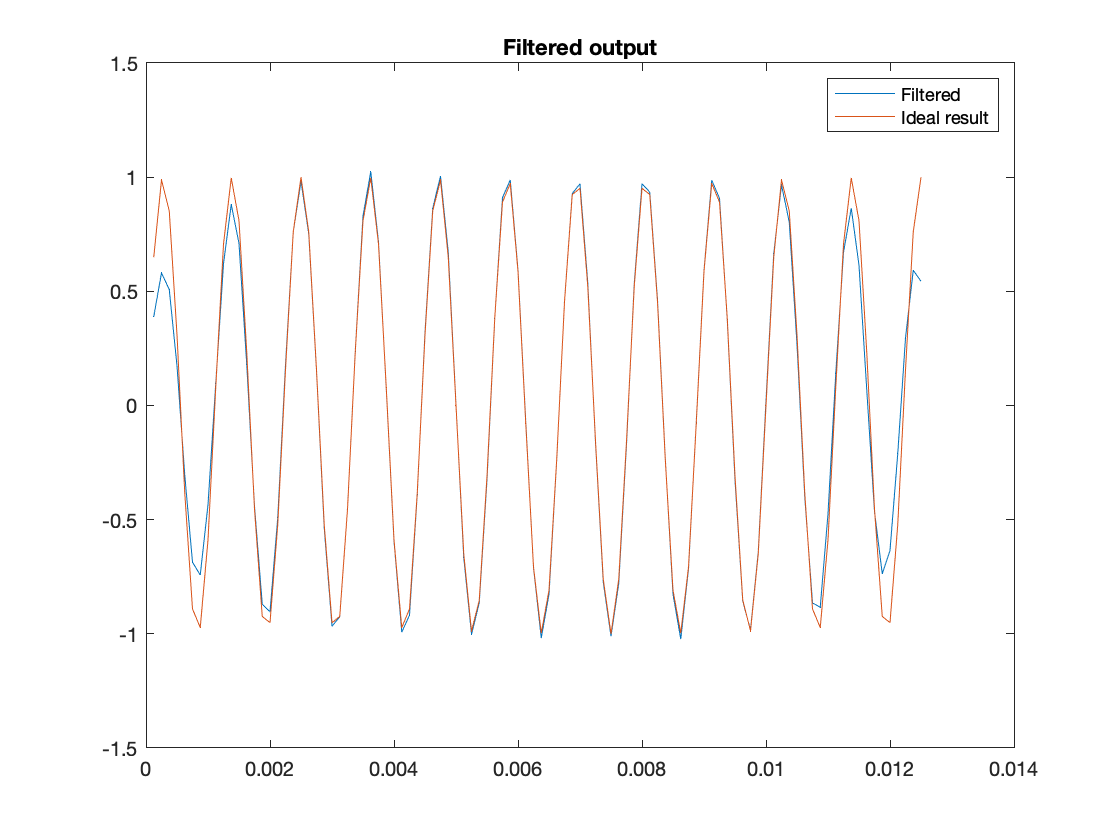

x_out = real(idtft(X_out, w, n));
plot(n*T, x_out, n*T, x2);
legend(["Filtered", "Ideal result"]); title("Filtered output");

c) On decresing the tolerances, the order of the filters will increase.

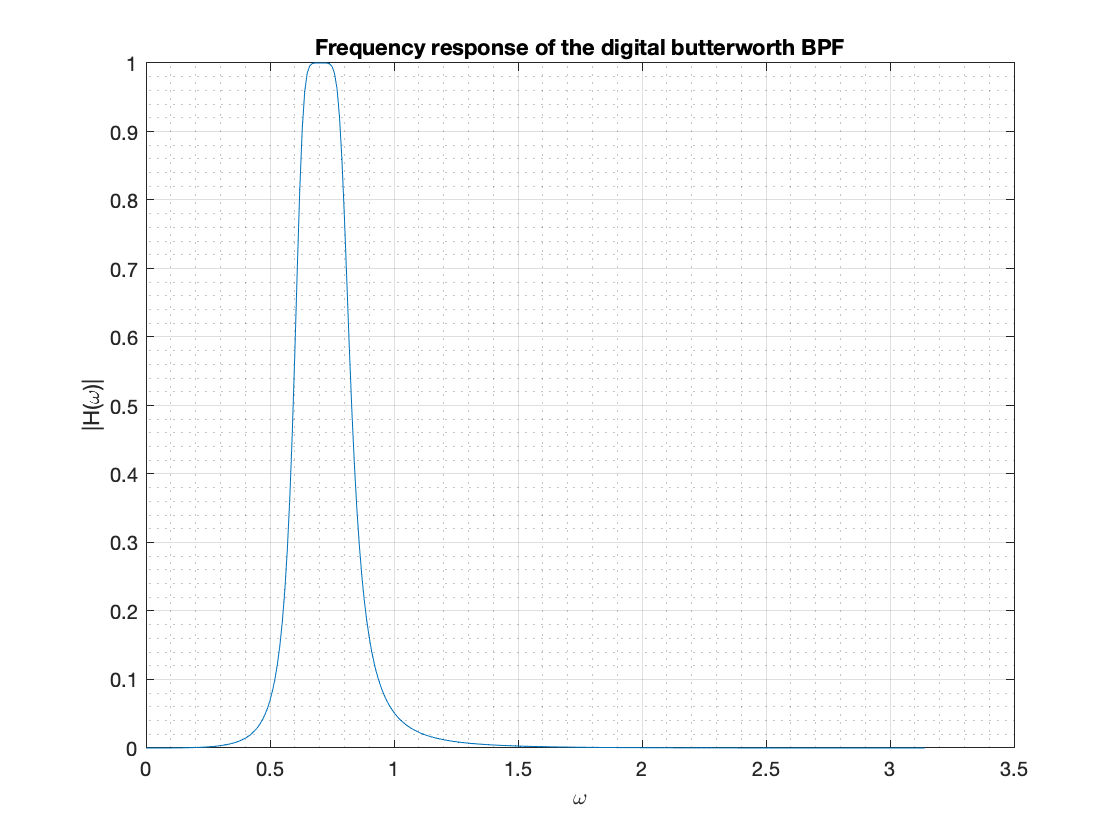

d_p	 d_s	 ws1	 wp1	 wp2	 ws2	 Nb
0.891	0.010	0.314	0.628	0.785	1.571	3.000	

% (c)
fp1 = 800;
fp2 = 1000;
fs1 = 400;
fs2 = 2000;
f_sampling = 8000;

%decreased tolerance
Ap_ = -1; %dB
As_ = -40; %dB
Hw_lower_tolerance = Hw_bpf(Ap_, As_, fp1, fp2, fs1, fs2, f_sampling);

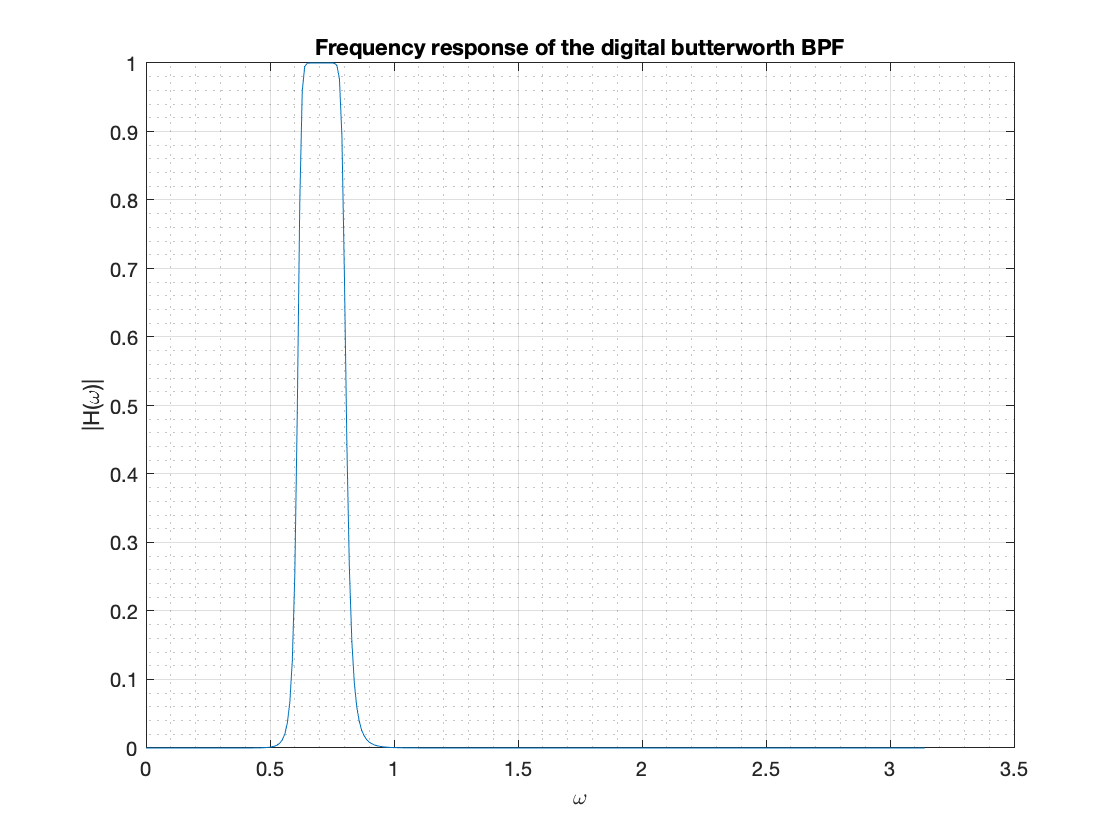

d_p	 d_s	 ws1	 wp1	 wp2	 ws2	 Nb
0.944	0.000	0.314	0.628	0.785	1.571	7.000	

Ap_ = -0.5;
As_ = -100;
Hw_lower_tolerance_2 = Hw_bpf(Ap_, As_, fp1, fp2, fs1, fs2, f_sampling);

d) On decreasing the transition bandwidth, the filter approaches an ideal filter. Also, the order of the filter starts to increase.

d_p	 d_s	 ws1	 wp1	 wp2	 ws2	 Nb
0.794	0.100	0.393	0.628	0.785	1.414	2.000	

Ap = -2; %dB
As = -20; %dB
f_sampling = 8000;

%decreased transition bandwidth
fp1_ = 800; fp2_ = 1000;
fs1_ = 500; fs2_ = 1800;
Hw_lower_tb = Hw_bpf(Ap, As, fp1_, fp2_, fs1_, fs2_, f_sampling);

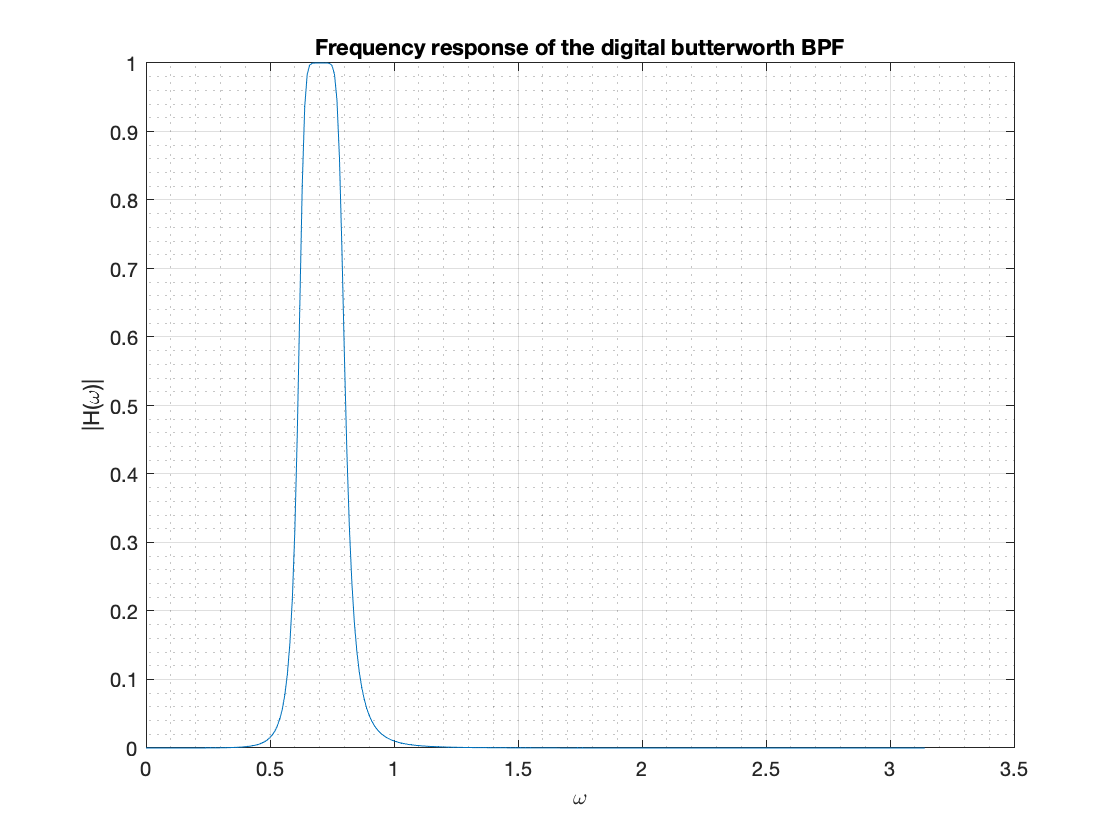

d_p	 d_s	 ws1	 wp1	 wp2	 ws2	 Nb
0.794	0.100	0.550	0.628	0.785	0.942	4.000	

fp1_ = 800; fp2_ = 1000;
fs1_ = 700; fs2_ = 1200;
Hw_lower_tb_2 = Hw_bpf(Ap, As, fp1_, fp2_, fs1_, fs2_, f_sampling);

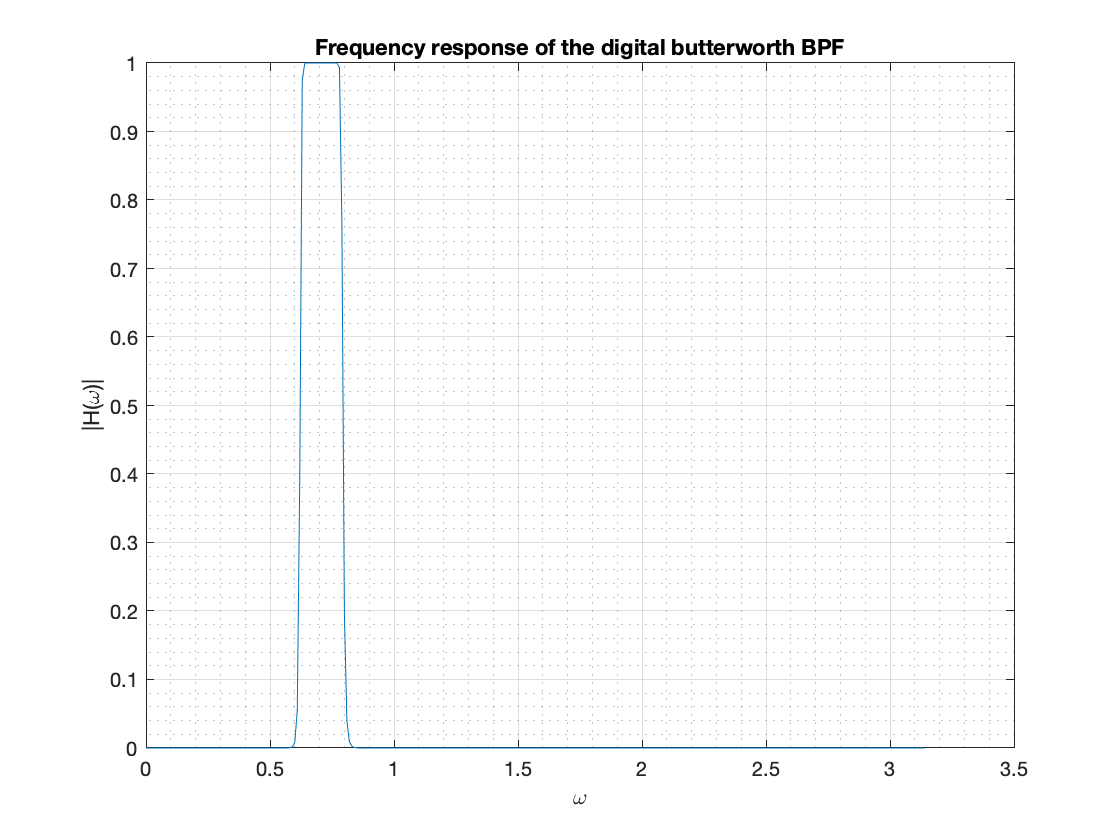

d_p	 d_s	 ws1	 wp1	 wp2	 ws2	 Nb
0.944	0.000	0.550	0.628	0.785	0.942	17.000	

% lower transition bandwidth and tolerance
Hw_lower_tb_tolrerance = Hw_bpf(Ap_, As_, fp1_, fp2_, fs1_, fs2_, f_sampling);

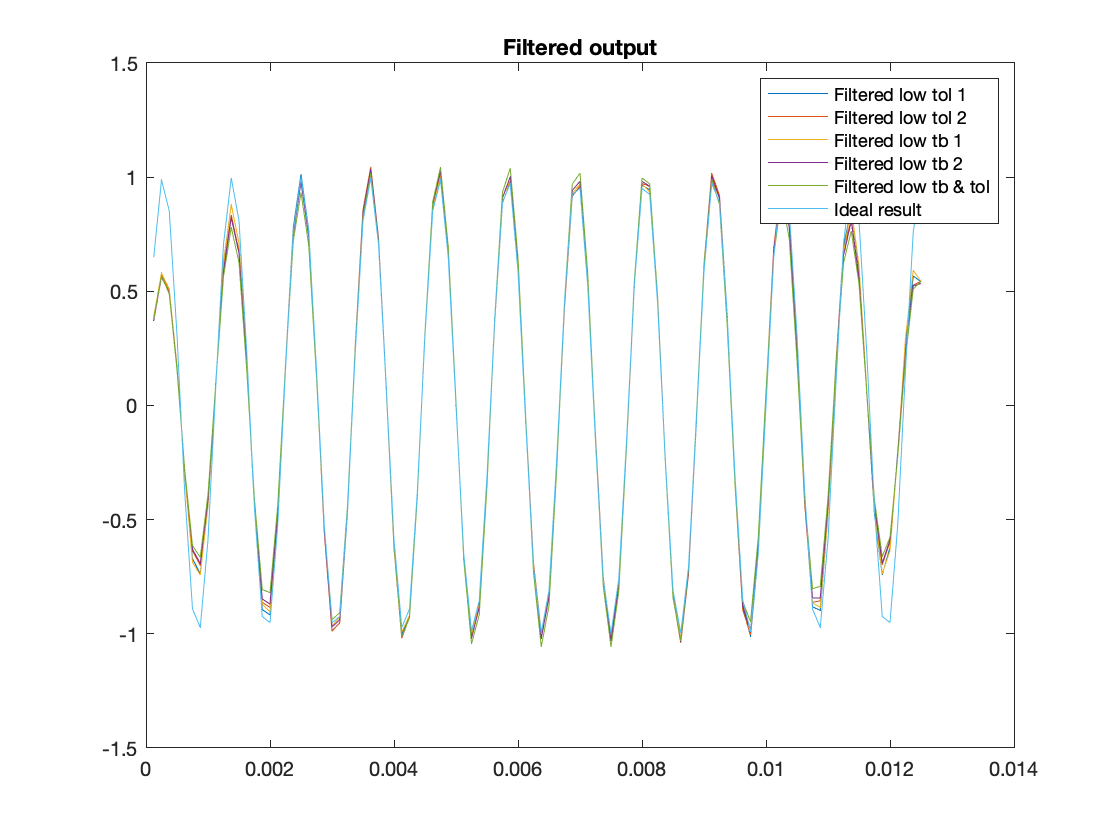

% observing the effects of changing parameters on filtered output
X_out1 = X_in .* Hw_lower_tolerance;
X_out2 = X_in .* Hw_lower_tolerance_2;
X_out3 = X_in .* Hw_lower_tb;
X_out4 = X_in .* Hw_lower_tb_2;
X_out5 = X_in .* Hw_lower_tb_tolrerance;

x_out1 = real(idtft(X_out1, w, n));
x_out2 = real(idtft(X_out2, w, n));
x_out3 = real(idtft(X_out3, w, n));
x_out4 = real(idtft(X_out4, w, n));
x_out5 = real(idtft(X_out5, w, n));

plot(n*T, [x_out1; x_out2; x_out3; x_out4; x_out5; x2]);
title("Filtered output");
legend(["Filtered low tol 1", "Filtered low tol 2",...
    "Filtered low tb 1", "Filtered low tb 2",...
    "Filtered low tb & tol", "Ideal result"]); 

function Hw = Hw_bpf(Ap, As, fp1, fp2, fs1, fs2, f_sampling)
    % Converting tolerance values from dB to magnitude
    dp = 10^(Ap/20);
    ds = 10^(As/20);
    
    % Normalised frequencies
    wp1 = 2*pi * fp1/f_sampling;
    wp2 = 2*pi * fp2/f_sampling;
    ws1 = 2*pi * fs1/f_sampling;
    ws2 = 2*pi * fs2/f_sampling;
    
    % Analog equivalent of frequencies
    Wp1 = tan(wp1/2);
    Wp2 = tan(wp2/2);
    Ws1 = tan(ws1/2);
    Ws2 = tan(ws2/2);
    % Center frequency and bandwidth
    W0 = sqrt(Wp1*Wp2);
    B = Wp2 - Wp1;
    
    % Modifyying specs if required
    if (Ws1*Ws2 < Wp1*Wp2)
        Ws1 = Wp1*Wp2 / Ws2;
    elseif (Ws1*Ws2 > Wp1*Wp2)
        Ws2 = Wp1*Wp2 / Ws1;
    end
    
    % Finding Normalised stopband frequency
    Wsn = (Ws2 - Ws1)/(Wp2 -  Wp1);
    
    % Designing Normalised Butterworth LPF
    Nb = ceil(log10(sqrt((ds^(-2) - 1)/(dp^(-2) - 1)))/log10(Wsn));
    Wcn = (dp^(-2) - 1)^(-0.5/Nb);
    
    % Normalised LPF Magnitude response
    Ha_nlpf = @(W) 1 ./ sqrt(1 + (W/Wcn).^(2*Nb));
    
    % Frequency transformation to get Denormalised BPF
    freq_transformation = @(W) (W.^2 - W0^2)./(W .* B);
    Ha_dnbpf = @(W) Ha_nlpf(freq_transformation(W));
    
    % Bilinear tranformation to get digital filter
    w = 0:0.01:pi;
    blt = @(w) tan(w/2);
    Hw = Ha_dnbpf(blt(w));
    
    figure;
    plot(w, Hw);
    grid on; grid minor; 
    xlabel("\omega"); ylabel("|H(\omega)|");
    title("Frequency response of the digital butterworth BPF");
    
    fprintf(sprintf("d_p\t d_s\t ws1\t wp1\t wp2\t ws2\t Nb")...
        + "\n" + sprintf("%0.3f\t", [dp, ds, ws1, wp1, wp2, ws2, Nb]));
end